clc; clear all; close all;
warning off;

## Pattern recognition course Practical assignment

Main "notebook" of the practical assignment. Includes the process from data gathering to accuracy calculations

### Data preprocessing

**Loading data into one large struct**

% The training data consists 100 time series for each number, lets gather
% all that into one large struct for easier data manipulation
[data,labels] = loadData();
A = data(8).pos; % Raw digit

[https://github.com/GMarzinotto/Leap-Motion-Gestures/blob/master/preprocessing_and_feature_extraction/center_digit.m](https://github.com/GMarzinotto/Leap-Motion-Gestures/blob/master/preprocessing_and_feature_extraction/center_digit.m)

**Exponential smoothing**

for i  = 1:length(data)
    numberTimeseries = data(i).pos(:,1:2);
    smoothed = expsmooth(numberTimeseries,500,10); % 500 10
    data(i).pos = smoothed; 
end
B = data(8).pos; %centered digit

**Look at the eigenvectors and use the eigenvectors to collect variability in x and y axis before minmax normalization**

for i  = 1:length(data)
    numberTimeseries = data(i).pos(:,1:2);
    
    [eigenvectors,eigenvalues] = eig(cov(numberTimeseries));
    eigenvector11(i) = eigenvectors(1,1);   
    eigenvector12(i) = eigenvectors(2,1);  
    eigenvector21(i) = eigenvectors(1,2);  
    eigenvector22(i) = eigenvectors(2,2);  
    eigenvalue1(i) = eigenvalues(1,1);
    eigenvalue2(i) = eigenvalues(2,2);
end

**Centering the data**

for i  = 1:length(data)
    numberTimeseries = data(i).pos(:,1:2);
    centered = center(numberTimeseries);
    data(i).pos = centered; 
end
C = data(8).pos; %centered digit

**PCA test (for each timeseries seperately)**

% for i  = 1:length(data)
%     numberTimeseries = data(i).pos(:,1:2);
%     centered = pcaFirst(numberTimeseries);
%     data(i).pos = centered; 
% end
% C = data(4).pos; %centered digit

PCA seems to only decrease accuracy. 

**Rescaling each digit using min max normalization**

% Normalizing the data so each number has same scale on different axis
for i = 1:length(data)
    numberTimeseries = data(i).pos(:,1:2); 
    rescaled = minmaxnorm(numberTimeseries);   
    data(i).pos = rescaled;
end
D = data(8).pos;

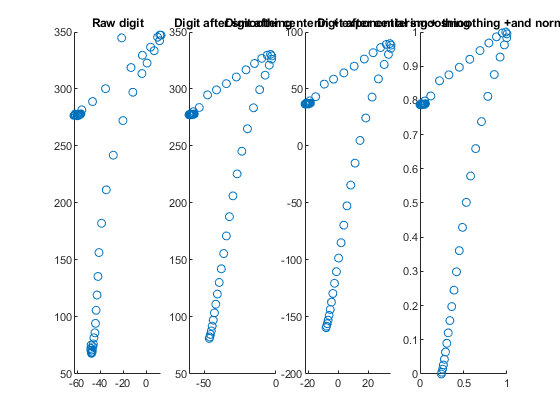

%plotting preprocessed data¨
subplot(141)
scatter(A(:,1),A(:,2))
title('Raw digit')
subplot(142)
scatter(B(:,1),B(:,2))
title('Digit after smoothing')
subplot(143)
scatter(C(:,1),C(:,2))
title('Digit after centerin + exponential smoothing')
subplot(144)
scatter(D(:,1),D(:,2))
title('Digit after centering + smoothing +and normalization')

**Transforming data into dataframe for easier use of classification algorithms**

Lets create a dataframe which has pixels as columns num. of columns = 12*12 pixels

One column for each pixel activation. Also calculate several features as extra columns, which could increase accuracy

% Creating array of 3D matrixes, where each matrix represents "pixel" of
% the number

pixelWidth = 12; % hyperparameter of the solution that could increase accuracy
dataWrangled = calculateFeatures(data,pixelWidth, ...
    eigenvector11,eigenvector12,eigenvector21,eigenvector22,eigenvalue1,eigenvalue2);


% testingMatlabBuiltIn = [dataWrangled,labels];
[temp,features] = size(dataWrangled);
%normalize the feature columns
dataWrangled(:,pixelWidth*pixelWidth:features) = minmaxnorm(dataWrangled(:,pixelWidth*pixelWidth:features));


Function to plot the numbers in dataframe form


% test2 = time2matrix2(data(7).pos,pixelWidth);
% % hold on
% % for i = 1:pixelWidth
% %     for j = 1:pixelWidth
% %         if test1(i,j) == 1
% %             plot(i,j,'ro')
% %         end
% %     end
% % end
% % hold off
% figure(2)
% hold on
% for i = 1:pixelWidth
%     for j = 1:pixelWidth
%         if test2(i,j) == 1
%             plot(i,j,'bo')
%         end
%     end
% end
% hold off

**Possible PCA to use for dimensionality reduction**

For some reason PCA only made the model accuracy lower

################ OBSOLETE

Doing PCA for the dataset 

TODO: do own function of the SVD

% [t,r2] = pcaOwn(dataWrangled);

Plotting PCA results

%Plotting pca results

% figure(1)
% plot(r2)
% title('Explained variance by number of principal components included')
% xlabel('Number of PC included')
% ylabel('Explained variance')

Lets choose the number of PC where explained variance is greater than 99.9%

% for i = 1:length(r2) % a loops that picks the number where 99.9% explained variability is gained first time
%     if r2(i) > 99.9
%         idx = i;
%         break;
%     end
% end
% fprintf('99%% explained variance is gained with %i PC:s',idx)

Picking less features from the dataset should prevent overleaning and therefore increase accuracy in the testing set. However this was not the case, and the accuracy seemed to only lower if PCA was done for the whole dataframe.

########## OBSOLETE

**Split data into testing and training**

Split the data to training and testing set. Since data wrangled matrix had numbers scrambled (10 samples in order contained 10 different numbers), we can just split the data by taking for example 20% first values to the validation set

%Splitting data into train and test

[train_data,train_data_y,validation_data,validation_data_y] = trainValidationSplit(dataWrangled,labels,0.50);



### Data classification algorithms

Try normal K-NN for the classification

Try out several methods and pick the one with the highest accuracy

**FKNN algorithm**

Using the template code provided in Pasi Luukkas Fuzzy data analysis course as basis, modifications where needed


[trainingSetAcc,validationACC,predictedLabels] = fknnModified(train_data,train_data_y,validation_data,validation_data_y);
fprintf("FKNN algorithm Training set ACC %2.2f%% and Test set acc %2.2f%%", trainingSetAcc,validationACC);


**Similarity algorithm using wrangled data**

Use the template code provided in Pasi Luukkas Fuzzy data analysis course as template, modifications where needed

[N,dims] = size(dataWrangled); 
v = [1:dims]; % columns of independent variables
c = dims+1;  % column of dependent variable

measure = 1; % Used similarity measure (see classifier.m) 
p = [0.1:0.2:4]; % p parameter range
m = [0.25:0.2:3]; % m parameter range 
pl=0; % Do we use plotting w.r.t. parameters p and m or not pl=0 no plotting pl=1 plotting.
N=20; %How many times data is divided into validation and training sets.
rn=1/2; % Now data is divided in half; half for the validation set and half for the training set.

% in simclass function data is expected to have labels on last column

data = [train_data,train_data_y];
[Mean_accuracy, Variance,p1,m1,pp,mm,id,maxacc] = simclass3(data,v,c, measure, p, m, N,rn,pl);
fprintf('FKNN algorihm accuracy %2.3f%%\n',Mean_accuracy);

**Similarity algorithm using time series data**

Similarity algorithm <-- this leads to poor results


% for j = 1:length(data)
%     test = data(j).pos; % Testing one written number
%     numDistances = zeros(10,1);
%     for i = 1:length(data)
%         distance = similarity(test,data(i).pos);
%         numDistances(labels(i)+1,1) = numDistances(labels(i)+1,1) + distance;
%     end
%     [val,idx] = min(numDistances);
%     predClass(j) = idx-1;
% end
% sum(predClass' == labels)

**Neural network algorithm**

Use the neural network function created for pattern recog and advanced data analysis & machine learning course. Using hyperparameters the number of layers, neurons within layers and activation functions can be changed

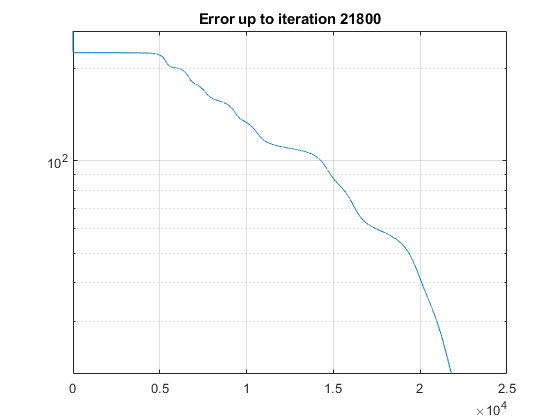

Classification accuracy 95.41%
NN layers: 2
10 neurons in layer 1 
10 neurons in layer 2 
Epoch error stop limit: 20


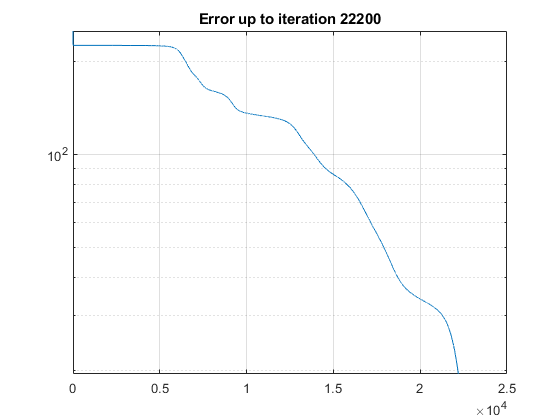

Classification accuracy 94.81%
NN layers: 2
10 neurons in layer 1 
10 neurons in layer 2 
Epoch error stop limit: 18


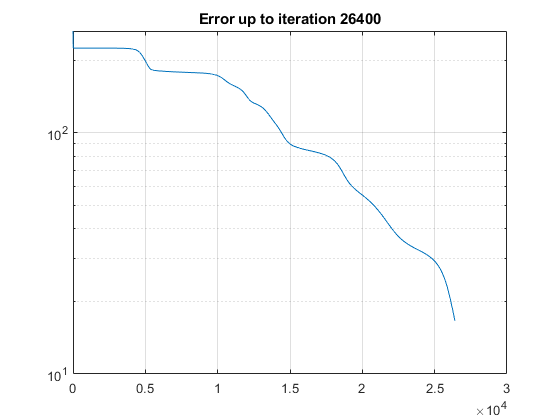

Classification accuracy 95.61%
NN layers: 2
10 neurons in layer 1 
10 neurons in layer 2 
Epoch error stop limit: 16


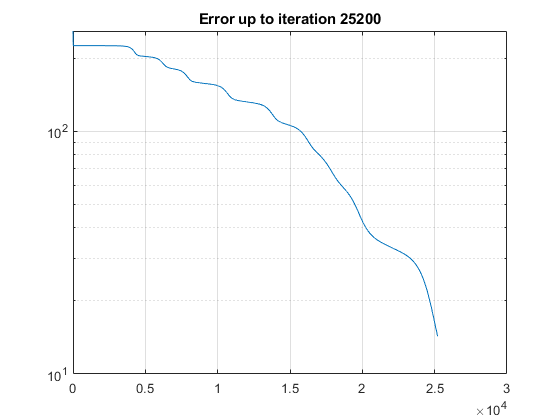

Classification accuracy 95.21%
NN layers: 2
10 neurons in layer 1 
10 neurons in layer 2 
Epoch error stop limit: 14


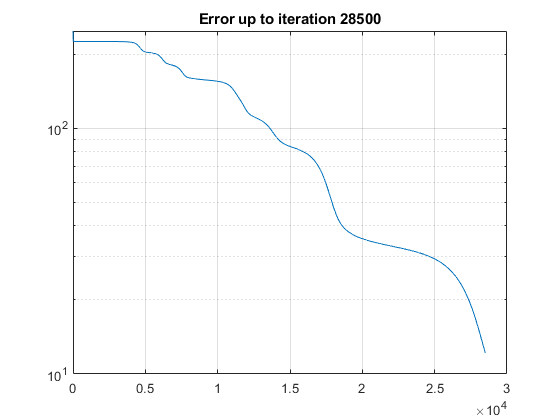

Classification accuracy 94.21%
NN layers: 2
10 neurons in layer 1 
10 neurons in layer 2 
Epoch error stop limit: 12


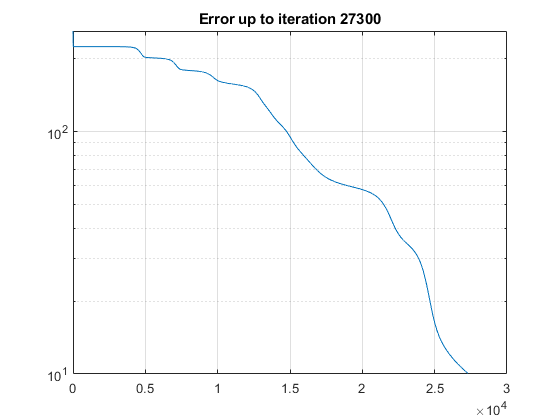

Classification accuracy 94.61%
NN layers: 2
10 neurons in layer 1 
10 neurons in layer 2 
Epoch error stop limit: 10


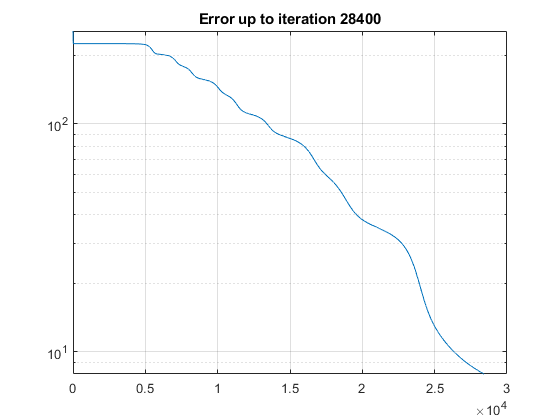

Classification accuracy 95.01%
NN layers: 2
10 neurons in layer 1 
10 neurons in layer 2 
Epoch error stop limit: 8


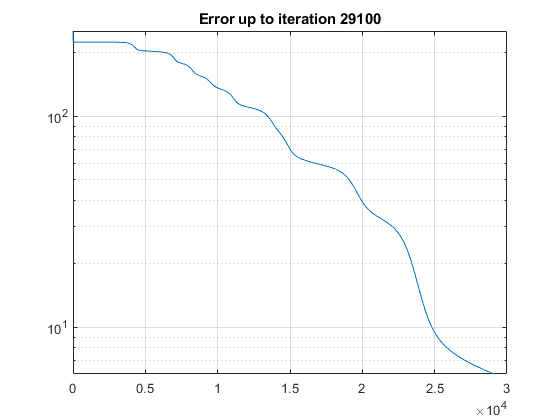

Classification accuracy 94.61%
NN layers: 2
10 neurons in layer 1 
10 neurons in layer 2 
Epoch error stop limit: 6


% for some retarded reason the function requires columns as datapoints and
% rows as features (built on top of the template given on pattern and adaml
% courses)
train_data2 = train_data'; train_data_y2 = [train_data_y'];
validation_data2 = validation_data'; validation_data_y2 = [validation_data_y'];

% 1 has to be added to each class, since the NN function does not
% understand zero class

train_data_y2 = train_data_y2 + 1;
validation_data_y2 = validation_data_y2 +1;


maxEpochs = 1000000; % number of iterations on NN backpropagation loop
classAcc = 0.1; classAccStored = 0; testClassStored = []; tstored = 1; wHiddenStored = {}; wOutputStored = {}; NNconfigStored = [];

actFunc = 'sigma'; % activation function
NNconfig = [10 10]; % configuration array for neural network architecture
for i = 20:-2:5
    stoplimit = i;
    [testClass, t, wHidden, wOutput,classAcc] = ...
  mlp_custom_v3(train_data2, train_data_y2, validation_data2, validation_data_y2, maxEpochs,actFunc,NNconfig,stoplimit);
  if classAcc > classAccStored
      classAccStored = classAcc;
      testClassStored = testClass;
      tstored = t;
      wHiddenStored = wHidden;
      wOutputStored = wOutput;
      NNconfigStored = NNconfig;
  end
end





% 
% load iris_dataset.mat
% train_data2 = irisInputs;
% train_data_y2 = [ones(50,1)',ones(50,1)'*2,ones(50,1)'*3];
% validation_data2 = irisInputs;
% validation_data_y2 = [ones(50,1)',ones(50,1)'*2,ones(50,1)'*3];
% maxEpochs = 100000; % number of iterations on NN backpropagation loop
% actFunc = 'sigma'; % activation function
% NNconfig = [10 10]; % configuration array for neural network architecture
% [testClass, t, wHidden, wOutput] = ...
%   mlp_custom_v3(train_data2, train_data_y2, validation_data2, validation_data_y2, maxEpochs,actFunc,NNconfig);


## Testing the digit_classify.m function

clc; clear all; close all;


[datafortest,labels] = loadData(); correct = 0; incorrect = 0; incorrectIdx = [];
for i  = 1:length(datafortest)
    Digit = datafortest(i).pos;
    DigitLabel = labels(i);
    C = digit_classify(Digit);
    if C == DigitLabel
        correct = correct+1;
    else
        incorrect = incorrect +1;
        incorrectIdx = [incorrectIdx i];
    end
end

% Seems to work

## Performance analysis

Examples of misclassified digits



for z  = 1:length(incorrectIdx)
    number = data(incorrectIdx(z)).pos;
    scatter(number(:,1),number(:,2))
    pause(5)
end

Unrecognized function or variable 'incorrectIdx'.

subplot(151)
scatter(data(incorrectIdx(1)).pos(:,1),data(incorrectIdx(1)).pos(:,2))
subplot(152)
scatter(data(incorrectIdx(2)).pos(:,1),data(incorrectIdx(2)).pos(:,2))
subplot(153)
scatter(data(incorrectIdx(3)).pos(:,1),data(incorrectIdx(3)).pos(:,2))
subplot(154)
scatter(data(incorrectIdx(4)).pos(:,1),data(incorrectIdx(4)).pos(:,2))
subplot(155)
scatter(data(incorrectIdx(5)).pos(:,1),data(incorrectIdx(5)).pos(:,2))


labels(incorrectIdx)

**Confusion matrix**

Kinda useless since there are so few misclassified digits.

--> Test with larger -% of data in testing set

confMat = zeros([10,10]);
for z = 1:length(testClassStored)
    i = testClassStored(z);
    j = validation_data_y2(z);
    confMat(i,j) = confMat(i,j) + 1;    
end

After the confusion matrix is created with this loop --> move data to excel and format.

Plotting of the data

% The size of the data

% plotNumber(data(812).pos);

% plotNumber(data(7).pos);

% pos = data(39).pos;
% [rows,dims] = size(pos);
% hold on
% for i = 1:rows-1
%     startx = pos(i,1);
%     endx = pos(i+1,1);
%     starty = pos(i,2);
%     endy = pos(i+1,2);
%     startz = pos(i,3);
%     endz = pos(i+1,3);
%     
%     plot([startx,endx],[starty,endy])    
% end
% hold off